# Traçage

## Accès dossier et choix essai

clear
Type = 'C6C0SN';
Materiau = '3135';
Eprouvette ='1';
Numero = '2';
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);  %Penser à ajouter strcat(Naming,'_','HDD.TXT') pour charger TDD/HDD/waveforms

load(strcat(Naming,'.mat'));

## Controles et paramètres des courbes 

###     Graphique 1 : 

Choix de la table pour abscisses et ordonnées : 

Table = 'HDD ' ;

Choix des variables et channel (si besoin) :

ParaX = "Time";
ParaY = "PARA1";
Channel = 0;

    (Le choix du channel n'est pas valable pour "Signaux cumulés")

% Selection des TDD par channel
TDDsauvegarde = TDD;
HDDsauvegarde = HDD;

% Extraction enveloppes (max et min) para 1 et 2 
[Max1,Min1,Max2,Min2] = enveloppePara(TDD,0.1,100);

if Channel==0
    TDD.RMS = TDD.RMS+TDD.RMS_1+TDD.RMS_2+TDD.RMS_3+TDD.RMS_4+TDD.RMS_5;
    TDD.ASL = TDD.ASL+TDD.ASL_1+TDD.ASL_2+TDD.ASL_3+TDD.ASL_4+TDD.ASL_5;
    TDD.ABS_ENERGY = TDD.ABS_ENERGY+TDD.ABS_ENERGY_1+TDD.ABS_ENERGY_2+TDD.ABS_ENERGY_3+TDD.ABS_ENERGY_4+TDD.ABS_ENERGY_5;
elseif not(Channel==1)
    TDD.RMS = TDD.(strcat('RMS_',string(Channel-1)));
    TDD.ASL = TDD.(strcat('RMS_',string(Channel-1)));
    TDD.ABS_ENERGY = TDD.(strcat('RMS_',string(Channel-1)));
end

if  not(Channel==0)
    selectHDD = find(HDD.CH==Channel);
    HDD = HDD(selectHDD,:);
end
% if Channel=='2'
%     HDD = HDD((t+1):end,1:end);
% end
HDD = sortrows(HDD,'Time'); 

% Affichage courbe 1
figure();
yyaxis left;
if Table=='HDD '
    plot(HDD.(ParaX),HDD.(ParaY),'.')
    xlabel(HDD.Properties.VariableDescriptions{ParaX});
    ylabel(HDD.Properties.VariableDescriptions{ParaY});
elseif Table=='TDD '
    plot(TDD.(ParaX),TDD.(ParaY),'-')
    xlabel(TDD.Properties.VariableDescriptions{ParaX});
    ylabel(TDD.Properties.VariableDescriptions{ParaY});
elseif Table=='CUMU'
    plot(CUMU.(ParaX),CUMU.(ParaY),'.')
    xlabel(CUMU.Properties.VariableDescriptions{ParaX});
    ylabel(CUMU.Properties.VariableDescriptions{ParaY});
end

--------------------------------------------------------------------------------------------------

courbe2 = true;

Choix de la table pour abscisses et ordonnées de la deuxième courbe  : 

Table2 = 'TDD ' ;

Choix des variables et channel (si besoin) :

ParaX2 = "Time";
ParaY2 = "PARA1";
Channel2 = 0;

    (Le choix du channel n'est pas valable pour "Signaux cumulés")

HDD = HDDsauvegarde;
TDD = TDDsauvegarde;

if Channel2==0
    TDD.RMS = TDD.RMS+TDD.RMS_1+TDD.RMS_2+TDD.RMS_3+TDD.RMS_4+TDD.RMS_5;
    TDD.ASL = TDD.ASL+TDD.ASL_1+TDD.ASL_2+TDD.ASL_3+TDD.ASL_4+TDD.ASL_5;
    TDD.ABS_ENERGY = TDD.ABS_ENERGY+TDD.ABS_ENERGY_1+TDD.ABS_ENERGY_2+TDD.ABS_ENERGY_3+TDD.ABS_ENERGY_4+TDD.ABS_ENERGY_5;
elseif not(Channel2==1)
    TDD.RMS = TDD.(strcat('RMS_',string(Channel2-1)));
    TDD.ASL = TDD.(strcat('RMS_',string(Channel2-1)));
    TDD.ABS_ENERGY = TDD.(strcat('RMS_',string(Channel2-1)));
end


if  not(Channel2==0)
    selectHDD = find(HDD.CH==Channel2);
    HDD = HDD(selectHDD,:);
end
HDD = sortrows(HDD,'Time'); 

% Affichage courbe 2
if courbe2==1
    hold;
    yyaxis right;
    if Table2=='HDD '
        plot(HDD.(ParaX2),HDD.(ParaY2),'r.')
        xlabel(HDD.Properties.VariableDescriptions{ParaX2});
        ylabel(HDD.Properties.VariableDescriptions{ParaY2});
    elseif Table2=='TDD '
        plot(TDD.(ParaX2),TDD.(ParaY2),'r-')
        xlabel(TDD.Properties.VariableDescriptions{ParaX2});
        ylabel(TDD.Properties.VariableDescriptions{ParaY2});
    elseif Table2=='CUMU'
        plot(CUMU.(ParaX2),CUMU.(ParaY2),'r.')
        xlabel(CUMU.Properties.VariableDescriptions{ParaX2});
        ylabel(CUMU.Properties.VariableDescriptions{ParaY2});
    end
    legend({Table,Table2});
    legend('Location','northwest');
end

Current plot held


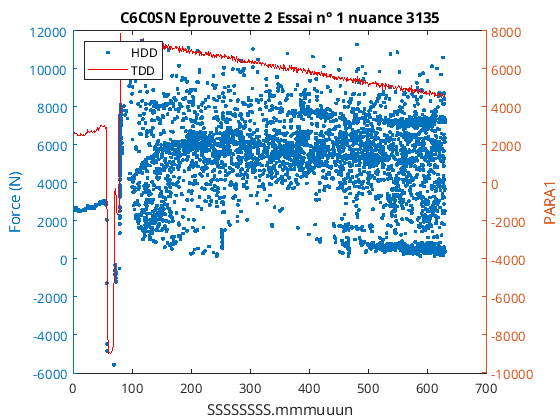

title(strcat(Type," ",'Eprouvette'," ",Numero," ",'Essai n°'," ",Eprouvette," ",'nuance'," ",Materiau))

% Rise time moyen
n = size(HDD);
RT = sum(HDD.RISE)/n(1);